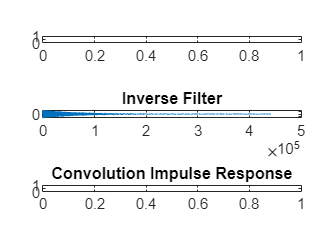

clc;

fs = 44100;
T = 10; %input('Enter duration in seconds ')/5;
f1 = 50; %input('Enter start frequncy (Hz) ');
f2 = 15000; %input('Enter end frequency (Hz) ');
nyq = fs/2;
wave1=2*pi*f1; %Generate sine wave
wave2=2*pi*f2; %^^^
silence = 5;
t=0:1/fs:(T*fs-1)/fs; %Length 
t=t';
K=T*wave1/log(wave2/wave1);
L=T/log(wave2/wave1); % Sweep rate
sweep=sin(K.*(exp(t/L)-1));
amplitudeEnvelope = [linspace(0, 1, length(sweep)), linspace(1, 1, length(sweep))];
inrec = audiorecorder(fs,24, 1);
record(inrec,T);
sound(sweep,fs,24) %% Play sound
pause(T+5);
sound(sweep,fs,24)
rec = getaudiodata(inrec);
invsweep=sweep(length(sweep):-1:1).*exp(-t./L);

a = rec;
a= a/max((abs(a)/3));
b = invsweep;
b= b/max((abs(b)/3));
ab = conv(a,b);
ab= ab/max(abs(ab));




subplot(3,1,2)
plot(b)
title('Inverse Filter');
subplot(3,1,3)
plot(ab)
title('Convolution Impulse Response');

N = length(rec);
subplot(3,1,1);     
X_mags = (abs(fft(ab)));
bin_vals = 0 : N;
fax_Hz = (bin_vals*fs/N);
N_2 = ceil(N/2);
plot(fax_Hz(1:N_2), 10*log10(X_mags(1:N_2)))